%Förbredelse uppgifter
% fråga 1: imagesc behöver en m-by-n matris

% fråga 2: colormap bestämmer färggradienten. Colormap gray mappar bilden i
% gråskala dvs svart till vit.

% fråga 3: nej :3


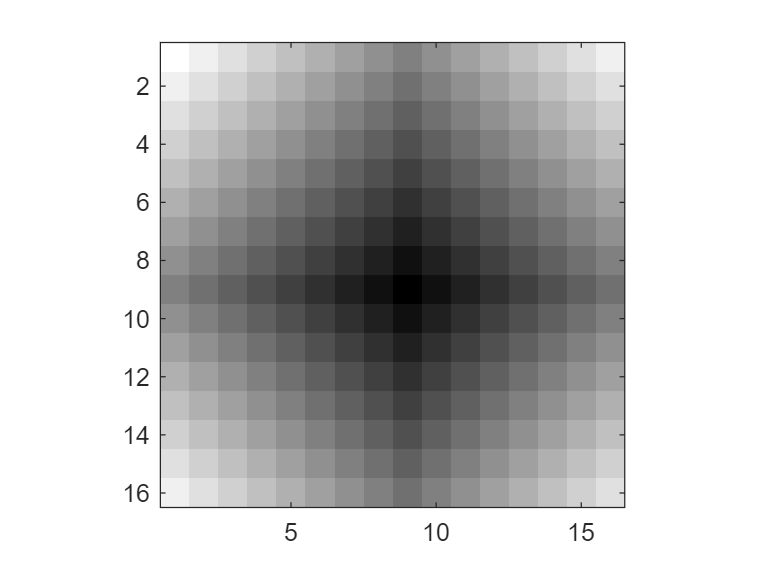

% 1.3
clear;
distance_map = zeros(16, 16);
for n  = 1:16
 for m = 1:16
    distance_map(n,m) = manhattan(n, m, 9, 9);
 end
end
figure;
imagesc(distance_map);
axis image;
colormap gray;

k = 0;
mask = (distance_map <= k);

mask = 16×16 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


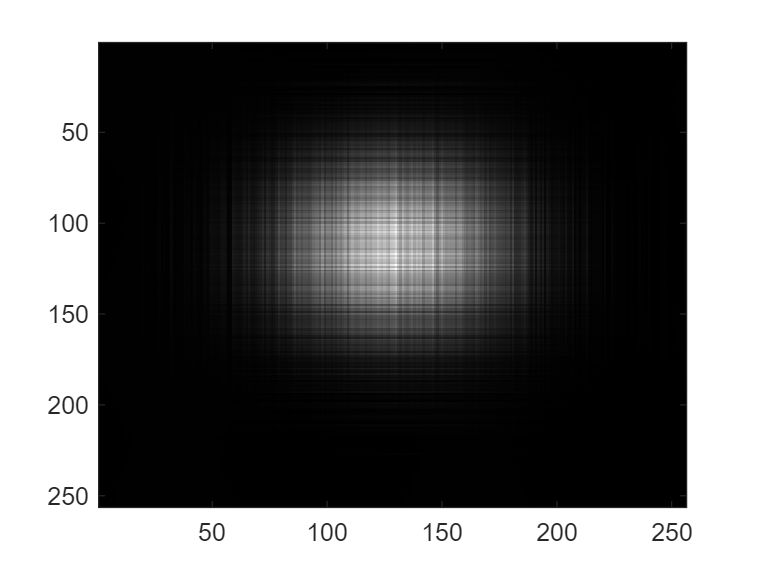

% 1.4
load("waves.mat");
ftwaves = fft2(waves);

imagesc(waves);


abs(ftwaves)

ans = 	1.0e+06 *

    1.2422    0.8677    0.3382    0.0623    0.0029    0.0074    0.0143    0.0111    0.0186    0.0139    0.0004    0.0044    0.0024    0.0075    0.0070    0.0038    0.0075    0.0143    0.0126    0.0061    0.0024    0.0041    0.0117    0.0114    0.0038    0.0046    0.0073    0.0085    0.0119    0.0148    0.0126    0.0160    0.0106    0.0040    0.0092    0.0206    0.0237    0.0157    0.0109    0.0112    0.0066    0.0054    0.0092    0.0089    0.0048    0.0154    0.0116    0.0052    0.0110    0.0042
    0.8792    0.6443    0.2502    0.0462    0.0022    0.0055    0.0106    0.0082    0.0138    0.0104    0.0003    0.0033    0.0018    0.0056    0.0052    0.0028    0.0056    0.0106    0.0094    0.0045    0.0018    0.0030    0.0087    0.0084    0.0028    0.0035    0.0054    0.0063    0.0088    0.0110    0.0094    0.0119    0.0079    0.0030    0.0068    0.0153    0.0176    0.0116    0.0081    0.0083    0.0049    0.0040    0.0068    0.0066    0.0035    0.0114    0.0086    0.0038 

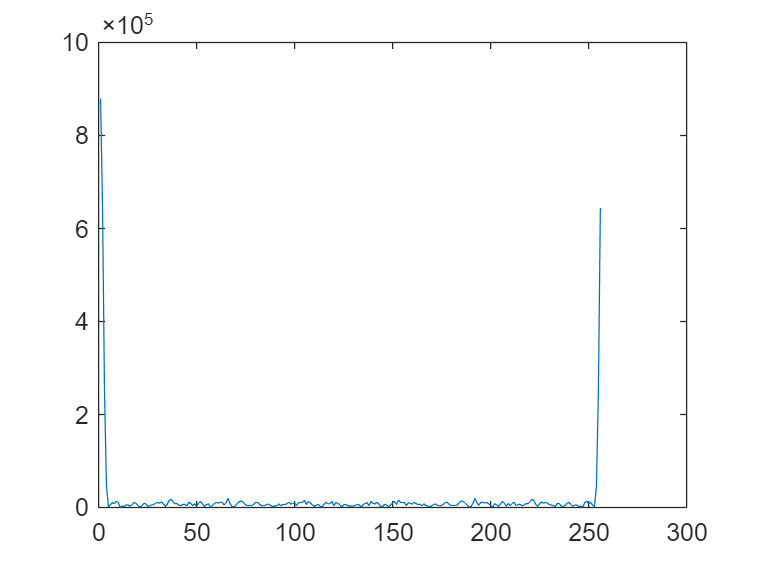

plot(abs(ftwaves(2,:)));

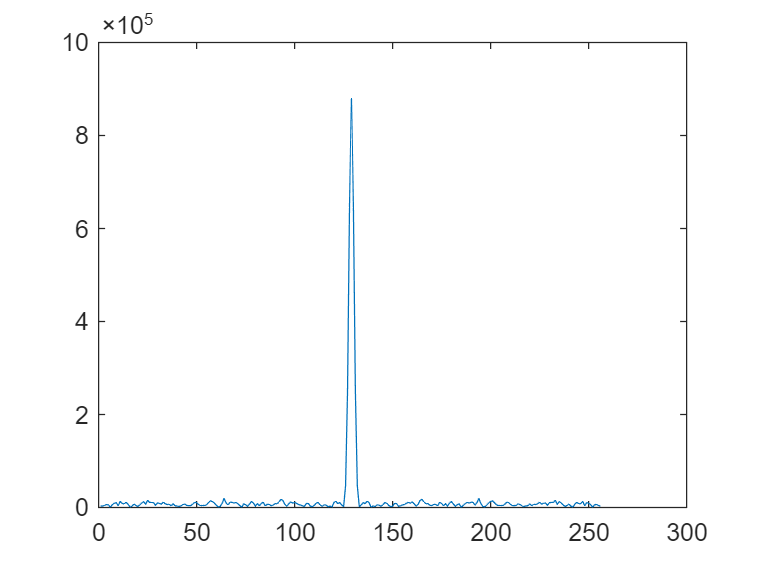

plot(abs(fftshift(ftwaves(2,:))));

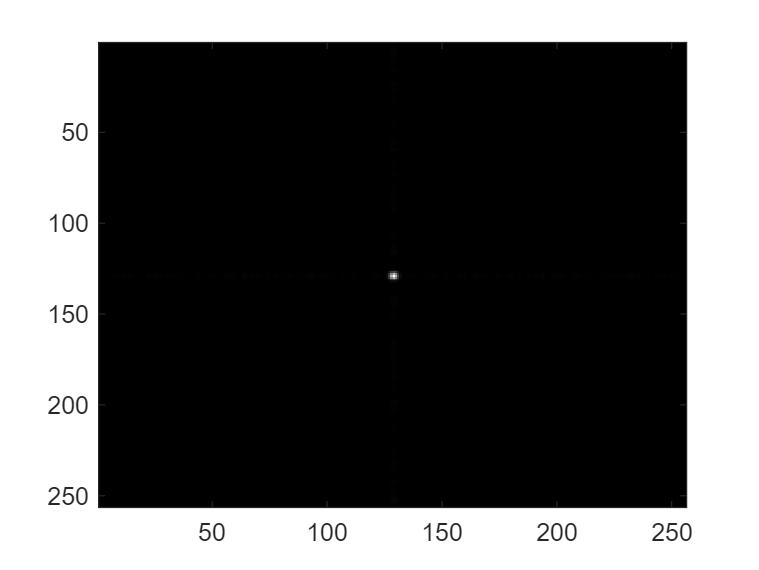


ftshitwaves = fftshift(ftwaves);
imagesc(abs(ftshitwaves));

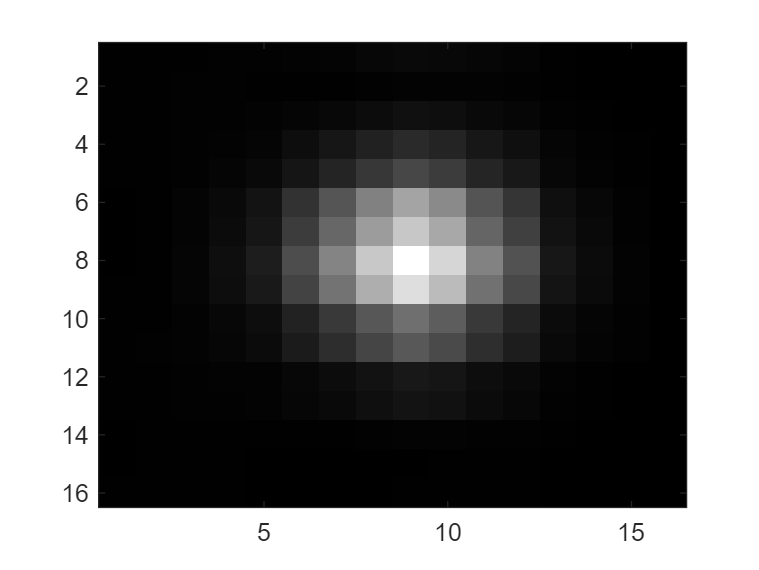


shortwaves = waves(1:16:256,1:16:256);
imagesc(abs(shortwaves));

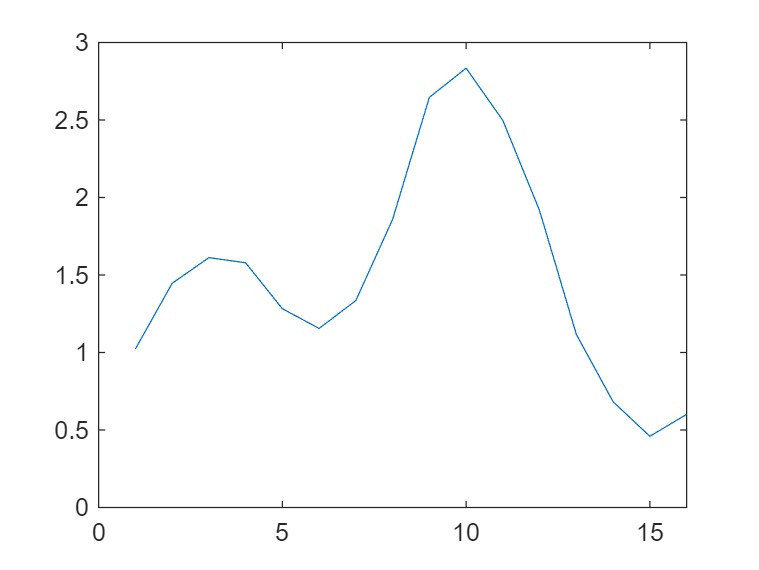

plot(abs(shortwaves(2,:)));

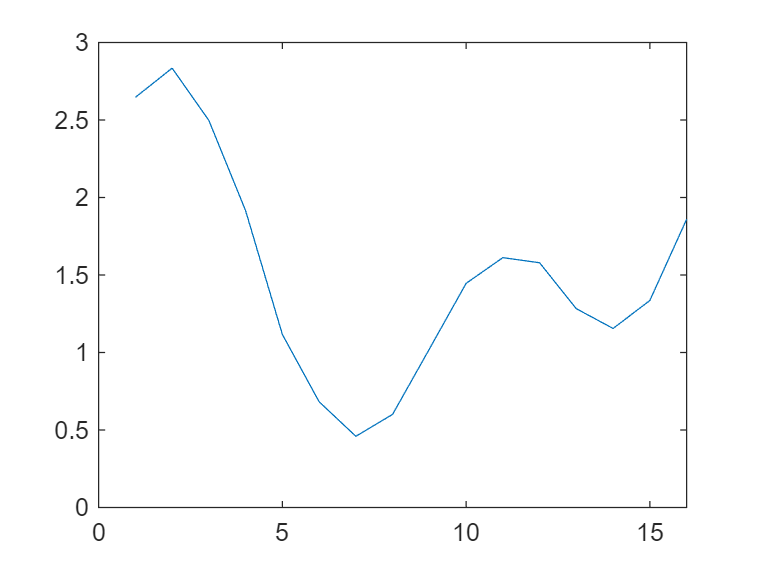

plot(abs(fftshift(shortwaves(2,:))));



sus = ifft2(fftshift(fftshift(fft2(shortwaves))));
gus = ifft2(fft2(shortwaves)); % ^^ the same thing :) fftshift two times reveses the function
pus = fftshift(fftshift(shortwaves));
kus = shortwaves;
%sus = gus = pus = kus

imagesc(gus)

imagesc(sus)

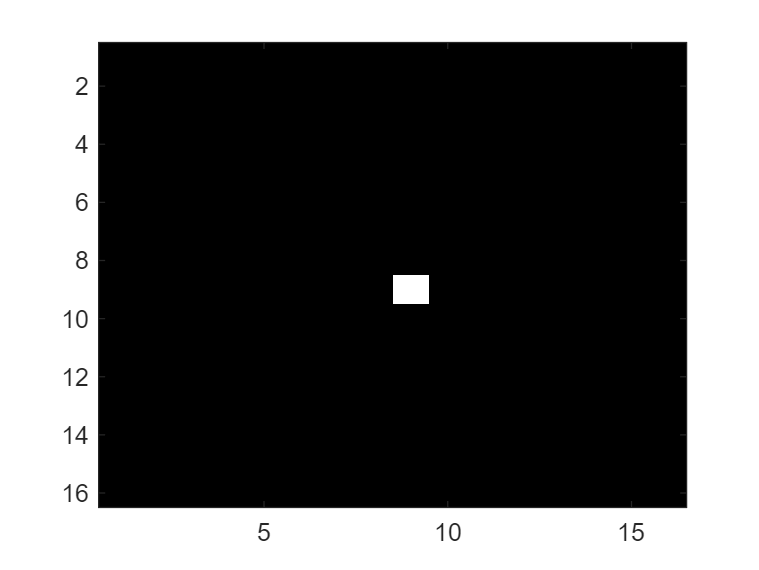

%sus - gus = 0
ftshortwaves = fft2(shortwaves);
ftshortwaves0 = fftshift(ftshortwaves) .* mask;

% rec0 = shortwaves * mask, shows the part of shortwaves which the mask lets through
rec0 = ifft2(fftshift(ftshortwaves0));

imagesc(ftshortwaves0); % shows the dot which the mask lets through

abs(rec0)

ans =    17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.71

real(rec0)

ans =    17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186   17.7186
   17.7186   17.7186   17.71

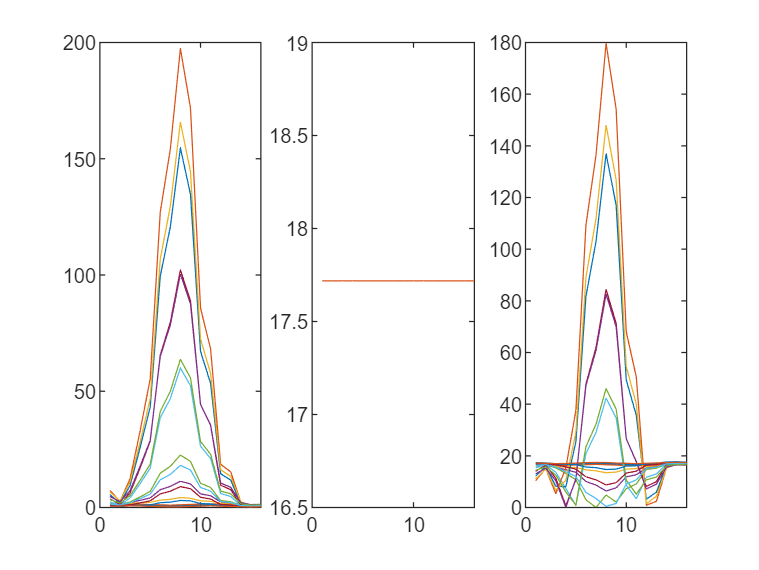


subplot(1,3,1), plot(shortwaves)
subplot(1,3,2), plot(real(rec0))
subplot(1,3,3), plot(abs(shortwaves-real(rec0)))

%frågor
    %För tröskelvärdet 0 sparade vi endast ett tal, vilket?
    %Svar: variabeln k=0 gav 1 värde (9,9)

    %Hur många tal sparade vi då tröskelvärdet var 1?
    %Svar: k=1 gav fyra värden

    %Hur många tal sparade vi då tröskelvärdet var 2?
    %Svar: 13 stycken värden

%Hur mycket komprimerar beror på tröskelvärdet, ju mindre destå mer
    %information kastar vi.
    % Sant

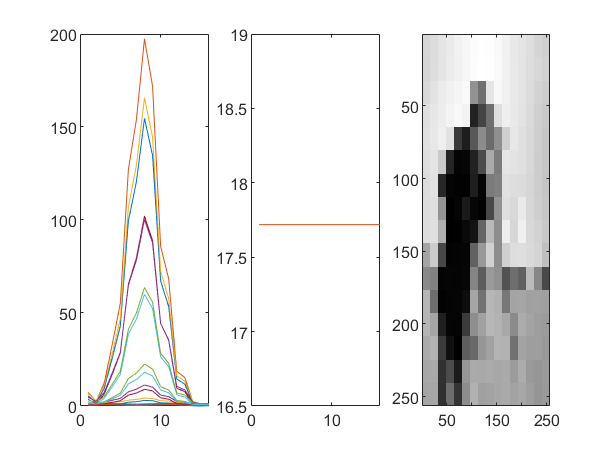

% 1.5
ORIGIM = imread('cameraman.tif');
ORIGIM = double(ORIGIM);

SFFTIMAGE = complex(zeros(size(ORIGIM)));
for k  = 1:16:size(ORIGIM,1)-15
 for m = 1:16:size(ORIGIM,2)-15
  SFFTIMAGE(k:k+15,m:m+15)=fftshift(fft2(ORIGIM(k:k+15,m:m+15)));
 end
end
RECIM = complex(zeros(size(ORIGIM)));
for mthres = 1:max(mask(:))+1
 for k  = 1:16:size(ORIGIM,1)-15
  for m = 1:16:size(ORIGIM,2)-15

    subimage = SFFTIMAGE(k:k+15,m:m+15) .* mask;

    RECIMAGE(k:k+15,m:m+15) = abs(ifft2(fftshift(subimage)));
  end
 end
 figure(1);imagesc(ORIGIM)
 figure(2);imagesc(RECIMAGE);
 %drawnow
 pause(0.2)
end